**Simulation Setup**

Configure the simulation parameters. For demonstrating basic OTFS concepts, let *M* = 64 and *N* = 30. Set the SNR to a high value to show the effects of ISI and ICI in different modulations and channel conditions.

M = 1024;          % number of subcarriers
N = 16;          % number of subsymbols/frame
df = 120e3;       % make this the frequency bin spacing of LTE
fc = 20e9;        % carrier frequency in Hz
padLen = 140;     % make this larger than the channel delay spread channel in samples
padType = 'ZP';  % this example requires ZP for ISI mitigation
SNRdB = 40;

**Grid Population for Channel Sounding**

Create an empty array of size *M*-by-*N* where the *M* rows correspond to the delay bins and the *N* columns map to the Doppler bins. To demonstrate how data in the delay-Doppler domain propagates through a high-mobility channel, place a pilot signal at grid position (1,16) to sound the channel. Leave the other grid elements empty so that the scatterer echoes will appear in the received delay-Doppler grid.

% Pilot generation and grid population
pilotBin = floor(N/2)+1;
Pdd = zeros(M,N);
Pdd(1,pilotBin) = exp(1i*pi/4); % populate just one bin to see the effect through the channel

**OTFS Modulation**

Modulate the DD data grid with the single pilot symbol using OTFS modulation. Use the `helperOTFSmod` function to operate the inverse Zak transform on the pilot grid `Pdd``.`

% OTFS modulation
txOut = helperOTFSmod(Pdd,padLen,padType);

**High-Mobility Channel**

Create an AWGN high-mobility channel with stationary transmitter and mobile receiver, and moving scatterers of different delays and Doppler shifts:

- Create a line-of-sight path representing the main propagation path from a base station to the receiver with zero delay and zero normalized Doppler. The line-of-sight path has zero delay and zero Doppler since the receiver is synchronized in time and frequency to the base station.

- Create scatterer 1 delayed five samples from the receiver and moving away from the receiver with Doppler of three times the normalized Doppler.

- Create scatterer 2 delayed eight samples from the receiver and moving towards the receiver with Doppler of five times the normalized Doppler.

% Configure paths
chanParams.pathDelays      = [0  5   8  ]; % number of samples that path is delayed
chanParams.pathGains       = [1  0.7 0.5]; % complex path gain
chanParams.pathDopplers    = [0 -3   5  ]; % Doppler index as a multiple of fsamp/MN

fsamp = M*df;            % sampling frequency at the Nyquist rate
Meff = M + padLen;       % number of samples per OTFS subsymbol
numSamps = Meff * N;     % number of samples per OTFS symbol
T = ((M+padLen)/(M*df)); % symbol time (seconds)

% Calculate the actual Doppler frequencies from the Doppler indices
chanParams.pathDopplerFreqs = chanParams.pathDopplers * 1/(N*T); % Hz

% Send the OTFS modulated signal through the channel
dopplerOut = dopplerChannel(txOut,fsamp,chanParams);

% Add white Gaussian noise
Es = mean(abs(pskmod(0:3,4,pi/4).^ 2));
n0 = Es/(10^(SNRdB/10));
chOut = awgn(dopplerOut,SNRdB,'measured');

Display the actual scatterer parameter delay and Doppler shift values to connect the normalized values to the actual values.

for k = 1:length(chanParams.pathDelays)
    fprintf('Scatterer %d\n',k);
    fprintf('\tDelay = %5.2f us\n', 1e6*chanParams.pathDelays(k)/(Meff*df));
    fprintf('\tRelative Doppler shift = %5.0f Hz (%5.0f km/h)\n', ...
        chanParams.pathDopplerFreqs(k), (physconst('LightSpeed')*chanParams.pathDopplerFreqs(k)/fc)*(3600/1000));
end

Scatterer 1


	Delay =  0.00 us


	Relative Doppler shift =     0 Hz (    0 km/h)


Scatterer 2


	Delay =  0.04 us


	Relative Doppler shift = -19794 Hz (-1068 km/h)


Scatterer 3


	Delay =  0.06 us


	Relative Doppler shift = 32990 Hz ( 1780 km/h)


**OTFS Demodulation**

To begin the demodulation process, the received signal vector is packed into an *M*-by-*N* matrix *Y**dt*. The Wigner transform is the inverse of the Heisenberg transform. Because this example uses rectangular pulse shaping, the Wigner transform is simply an OFDM demodulation operation. Following the Wigner transform, the SFFT converts the time-frequency domain grid into the delay-Doppler domain.

In this example, use the more efficient Zak transform to demodulate the signal:


$$Y_{dd}[k,l]=M\ast FFT(Y^T_{dt})^T.$$


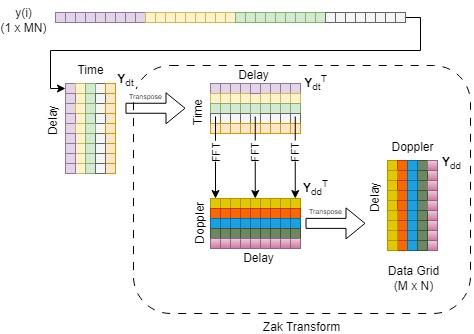

Collect samples in an OTFS frame and demodulate the signal in the delay-Doppler domain.

% Get a sample window
rxIn = chOut(1:numSamps);

% OTFS demodulation
Ydd = helperOTFSdemod(rxIn,M,padLen,0,padType);

**Delay-Doppler Channel Response**

The output of the OTFS demodulated signal is the convolution of the pilot signal transmitted at (1,16) with the channel representation in the DD domain (5,-10) and (8,6). This is different than OFDM demodulation, where the OFDM demodulated signal is the Hadamard (element-by-element) product of the OFDM symbol with the frequency-domain channel coefficients.

A linear minimum mean square error (LMMSE) estimator is an estimation method that minimizes the mean square error between an observation *Y* (the received signal) and the actual value *P* (the known pilot signal), and is given as:


$$\hat{P}_{LMMSE}=\frac{Y\ast P^\ast }{|P|^2+\sigma ^2_n}$$


where *P*∗ is the complex conjugate of *P* and $\sigma ^2_n$ is the noise power. To estimate the channel response in the delay-Doppler domain, use LMMSE on each grid element *Ydd*[*k*,*l*] against the single pilot symbol *Pdd* and compute the channel response *Hdd*.

## 2) Intuición de la fórmula LMMSE escalar

Fórmula que muestras (escala por escala):$\hat{H}_{\text{LMMSE}} = \frac{Y \cdot P^*}{|P|^2 + \sigma_n^2}$�

**Modelo elemental** (por celda DD, escala):

Supón que en una celda particular (k,l) se tiene el modelo lineal simple


$$Y = H\;P \;+\; n$$


donde:

- P es el valor del piloto (conocido),

- H es el coeficiente del canal en esa celda (lo que queremos estimar),

- n es ruido aditivo, $E[n]=0,\; E[|n|^2]=\sigma_n^2$.

Queremos estimar H a partir de la observación Y usando un estimador lineal (LMMSE = mejor estimador lineal en MSE). Buscamos un estimador de la forma $\hat H = c\,Y$ (constante compleja c) que minimice $E[|H - cY|^2]$.

**Derivación breve**

Minimiza $J(c) = E[|H - cY|^2]$. Derivar respecto a $c^*$ y anular:


$$\frac{\partial J}{\partial c^*} = -E[H Y^*] + c\,E[|Y|^2] = 0 \;\Rightarrow\; c = \frac{E[H Y^*]}{E[|Y|^2]}.$$


Calcular las expectativas asumiendo independencia H y n, y asumiendo $E[H]=0$ o simplemente usando su varianza $\sigma_H^2 = E[|H|^2]$:

- $E[H Y^*] = E[H (H P + n)^*] = E[|H|^2] P^* + E[H n^*] = \sigma_H^2 P^*$ (si H independiente de n, término cruzado 0).

- 
$$E[|Y|^2] = E[|H P + n|^2] = |P|^2 E[|H|^2] + E[|n|^2] = |P|^2 \sigma_H^2 + \sigma_n^2.
$$


Entonces$c = \frac{\sigma_H^2 P^*}{|P|^2 \sigma_H^2 + \sigma_n^2}.$

La estimación es


$$\hat H = c Y = \frac{\sigma_H^2 P^*}{|P|^2 \sigma_H^2 + \sigma_n^2} \;Y.$$


Si ahora **normalizas** tomando $\sigma_H^2 = 1$ (o si la expresión que usas asume unidad de varianza para HHH) obtienes la forma simplificada usada por el script:


$$\hat H = \frac{Y P^*}{|P|^2 + \sigma_n^2}.
$$


% LMMSE channel estimate in the delay-Doppler domain
% En si, es la estimación del canal, pero desplazado 
% por el piloto, luego se centra en el piloto para obtener
% la respuesta absoluta del canal
Hdd = Ydd * conj(Pdd(1,pilotBin)) / (abs(Pdd(1,pilotBin))^2 + n0);

Visualize the received DD grid with a mesh plot.

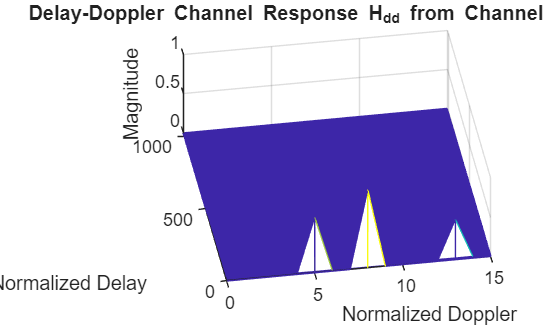

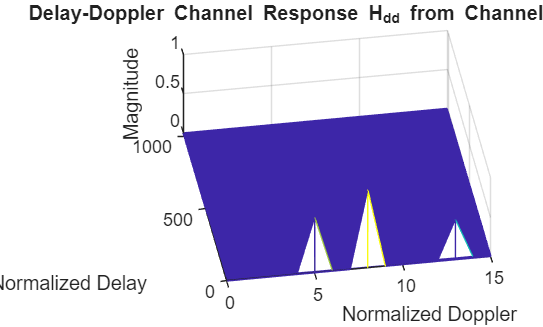

figure;
xa = 0:1:N-1;
ya = 0:1:M-1;
mesh(xa,ya,abs(Hdd));
view([-9.441 62.412]);
title('Delay-Doppler Channel Response H_{dd} from Channel Sounding');
xlabel('Normalized Doppler');
ylabel('Normalized Delay');
zlabel('Magnitude');

The DD grid from the channel sounding shows all the paths seen by the receiver from the single pilot, the delay of each path, the Doppler shift of each path, and the complex gain of each path. Observe how the pilot symbol convolves with the DD channel response in the delay-Doppler domain. The pilot is correctly received at the proper grid position (1,16). The other two scatterers also appear in the DD grid.

- Scatterer 1 is at grid position (1,16) + (5,-3) = (6,13).

- Scatterer 2 is at grid position (1,16) + (8,5) = (9,21).

**Channel Estimation**

Channel estimation in the delay-Doppler domain requires estimating the parameters (delay, Doppler, and complex gain) of all the scatterers in the channel response. From the channel response *H**dd*, find paths that exceed a preset gain threshold and store the parameters for each unique path. Store the channel estimates for later use when transmitting data over the same channel.

[lp,vp] = find(abs(Hdd) >= 0.05);
idx = sub2ind(size(Hdd), lp, vp);
chanEst.pathGains = Hdd(idx);           % get path gains
chanEst.pathDelays = lp - 1;            % get delay indices
chanEst.pathDopplers = vp - pilotBin;   % get Doppler indices

**OTFS Over High-Doppler Channel**

Transmit the same data grid using OTFS modulation.

% Data generation
Xgrid = zeros(M,N);
Xdata = randi([0,1],2*M,N);
Xgrid(1:M,:) = pskmod(Xdata,4,pi/4,InputType="bit");

% OTFS modulation
txOut = helperOTFSmod(Xgrid,padLen,padType);

% Add channel and noise
dopplerOut = dopplerChannel(txOut,fsamp,chanParams);
chOut = awgn(dopplerOut,SNRdB,'measured');

A generic signal model is given as *y*=*Gx*+*n*, where *x* and *y* are the time-domain signals of length *MN* transmitted into the channel and received from the time-domain channel matrix *G*, respectively. If *G* is known, LMMSE can be used to equalize the channel [[4](https://la.mathworks.com/help/comm/ug/otfs-modulation.html#mw_rtc_OTFSModulationExample_M_97A32743)]. In matrix form, the LMMSE is given as:


$$\hat{x}=(G^HG+\sigma ^2_nI_{M*N})^{-1}G^Hy.$$


By equalizing in the time domain, you can use the information of the delay and Doppler shifts of the individual paths to remove the ICI. Form the channel matrix from the delay-Doppler channel parameter estimates found earlier.

Este termino $(G^HG+\sigma ^2_nI_{M*N})^{-1}G^H$ es el que minimiza el error entre el x estimado y el real. En la forma más general $\hat{x}=(H^TH)^{-1}H^Ty$, que es la forma de hacer una regresión lineal cuando la matriz es rectangular o singular, y si hay ruido se agrega el termino del ruido $\hat{x}=(H^TH+n_0I)^{-1}H^Ty$. Pero en el caso de ser una matriz cuadrada no singular, se tiene que $x=H^{-1}y$.

% Form G matrix using channel estimates
G = getG(M,N,chanEst,padLen,padType);

Equalize and detect the received data using LMMSE in the delay-Doppler domain. Assume the noise power is known.

rxWindow = chOut(1:numSamps);
y_otfs = ((G'*G)+n0*eye(Meff*N)) \ (G'*rxWindow); % LMMSE

Xhat_otfs = helperOTFSdemod(y_otfs,M,padLen,0,padType); % OTFS demodulation

Show that the received constellation is cleaner than the OFDM constellation.

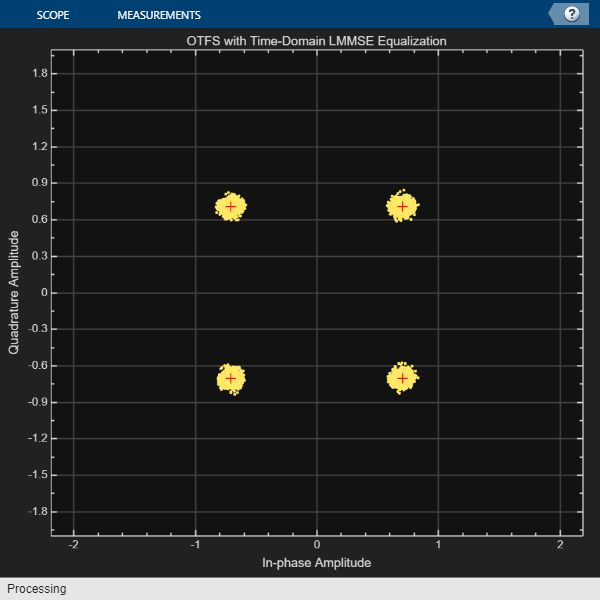

constDiagOTFS = comm.ConstellationDiagram( ...
    ReferenceConstellation=pskmod(0:3,4,pi/4), ...
    AxesLimits=[-2 2], ...
    Title='OTFS with Time-Domain LMMSE Equalization');
constDiagOTFS(Xhat_otfs(:));


XhatDataOTFS = pskdemod(Xhat_otfs,4,pi/4,OutputType="bit",OutputDataType="logical");
[~,berOTFS] = biterr(Xdata,XhatDataOTFS);
fprintf('OTFS BER with LMMSE equalization = %3.3e\n', berOTFS);

OTFS BER with LMMSE equalization = 0.000e+00


**Support Functions**

function y = dopplerChannel(x,fs,chanParams)
    % Form an output vector y comprising paths of x with different
    % delays, Dopplers, and complex gains
    numPaths = length(chanParams.pathDelays);
    maxPathDelay = max(chanParams.pathDelays);
    txOutSize = length(x);
    
    y = zeros(txOutSize+maxPathDelay,1);
    
    for k = 1:numPaths
        pathOut = zeros(txOutSize+maxPathDelay,1);

        % Doppler
        pathShift = frequencyOffset(x,fs,chanParams.pathDopplerFreqs(k));
    
        % Delay and gain
        pathOut(1+chanParams.pathDelays(k):chanParams.pathDelays(k)+txOutSize) = ...
            pathShift * chanParams.pathGains(k);
            
        y = y + pathOut;
    end
end

function G = getG(M,N,chanParams,padLen,padType)
    % Form time domain channel matrix from detected DD paths
    if strcmp(padType,'ZP') || strcmp(padType,'CP')
        Meff = M + padLen;  % account for subsymbol pad length in forming channel
        lmax = padLen;      % max delay
    else
        Meff = M;
        lmax = max(chanParams.pathDelays);  % max delay
    end
    MN = Meff*N;
    P = length(chanParams.pathDelays);  % number of paths
    
    % Form an array of channel responses for each path
    g = zeros(lmax+1,MN);
    for p = 1:P
        gp = chanParams.pathGains(p);
        lp = chanParams.pathDelays(p);
        vp = chanParams.pathDopplers(p); 

        % For each DD path, compute the channel response.
        % Each path is a complex sinusoid at the Doppler frequency (kp)
        % shifted by a delay (lp) and scaled by the path gain (gp)
        g(lp+1,:) = g(lp+1,:) + gp*exp(1i*2*pi/MN * vp*((0:MN-1)-lp));
    end    

    % Form the MN-by-MN channel matrix G
    G = zeros(MN,MN);
    % Each DD path is a diagonal in G offset by its path delay l
    for l = unique(chanParams.pathDelays).'
        G = G + diag(g(l+1,l+1:end),-l);
    end
end